cd('/Volumes/PrecunealSSD2/HCP/AWS/hcp-openaccess/HCP_1200');
as = mlraut.AnalyticSignalHCP( ...
    subjects={'995174'}, ...
    tasks={'rfMRI_REST1_RL'}, ...
    do_save=false, ...
    force_band=false, ...
    hp_thresh=0.01, ...
    lp_thresh=0.1, ...
    tags=stackstr(use_dashes=true), ...
    source_physio="iFV", ...
    global_signal_regression=true);

as.current_subject = as.subjects{1};
if ~contains(as.out_dir, as.current_subject)
    as.out_dir = fullfile(as.out_dir, as.current_subject);
    ensuredir(as.out_dir);
end

as.current_task = as.tasks{1};

as

as =   AnalyticSignalHCP with properties:

                      num_nets: 9
                       num_sub: 1
                     num_tasks: 1
               analytic_signal: []
                   HCP_signals: []
                   do_plot_emd: 0
         do_plot_global_physio: 0
              do_plot_networks: 0
                 do_plot_radar: 0
                       do_save: 0
                do_save_ciftis: 0
       do_save_ciftis_of_diffs: 0
               do_save_dynamic: 0
                    force_band: 0
           final_normalization: "normxyzt"
                 source_physio: "iFV"
                  anatomy_list: {'cbm'  'ctx'  'str'  'thal'}
                 global_signal: []
      global_signal_regression: 1
                     hp_thresh: 0.0100
                     lp_thresh: 0.1000
                      rsn_list: {'visual'  'somatomotor'  'dorsal attention'  'ventral attention'  'limbi

%% parameters for aufbau

select_network_type = "cortical";  % "cortical", "thalamic", "striatal", "cerebellar"
select_rsn = 'visual';
NETWORKS_YEO_NAMES = ...
    {'visual', 'somatomotor', 'dorsal attention', 'ventral attention', 'limbic', ...
    'frontoparietal', 'default mode', ...
    'task+', 'task-'};
bool_select_rsn = contains(NETWORKS_YEO_NAMES, select_rsn);
num_frames = as.num_frames;  % 417;  % as.num_frames;

tf = (num_frames - 1)*as.tr;
t = 0:as.tr:tf;

Late Hilbert transform

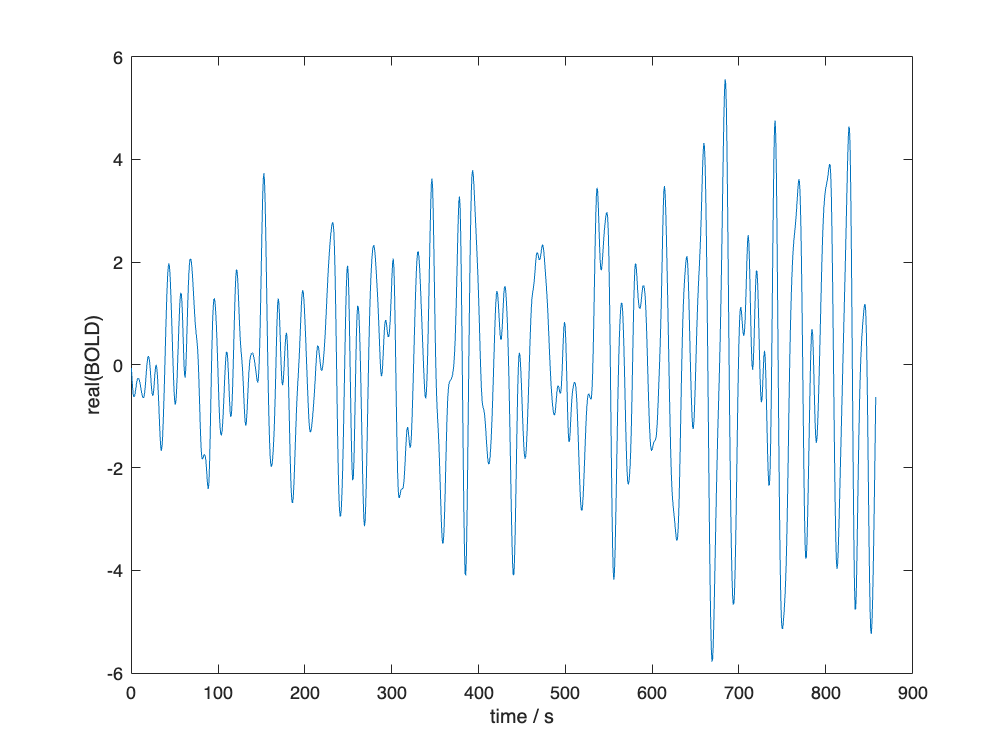

ctx = as.average_network_signal(as.task_dtseries(), network_type=select_network_type);

bold_gsr_ =  ...
    as.build_global_signal_regressed(ctx(:, bool_select_rsn));
bold_ = as.build_band_passed( ...    
    as.build_centered_and_rescaled(bold_gsr_));

figure; plot(t, bold_(1:num_frames))
ylabel("real(BOLD)")
xlabel("time / s")

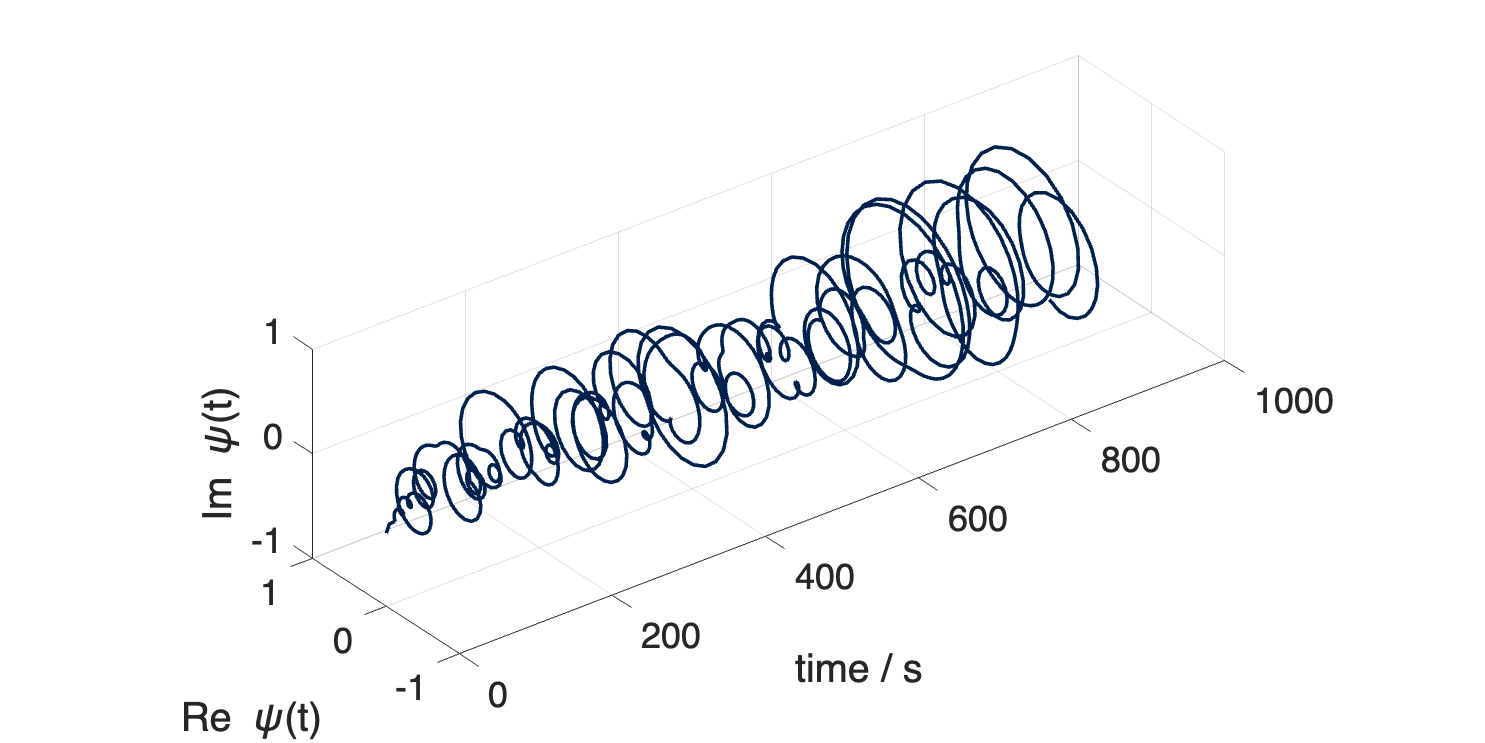

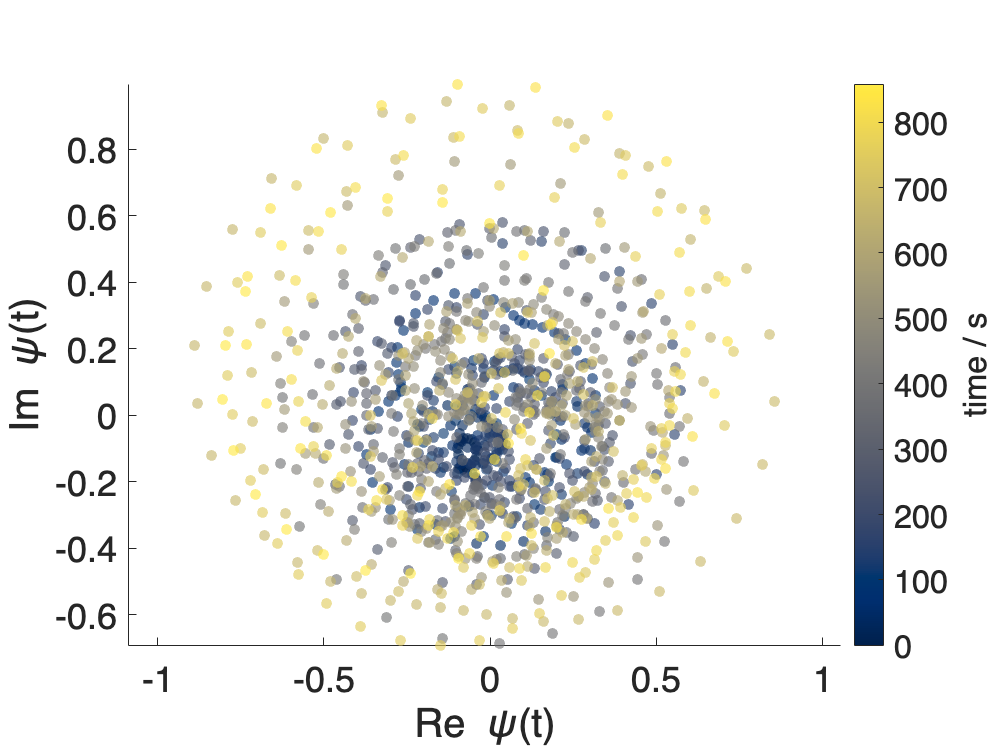


bold_signal_ = ...
    as.build_final_normalization( ...
    hilbert(bold_(1:num_frames, :)));

as.plot3(num_frames=num_frames, t=t, z=bold_signal_, title="")

r = abs(bold_signal_);
theta = angle(bold_signal_);
fprintf("mean(bold(x,t)) -> %g exp(%gi)\n", mean(r, "all"), mean(theta, "all"))

mean(bold(x,t)) -> 0.372692 exp(-0.109595i)


fprintf("median(bold(x,t)) -> %g exp(%gi)\n", median(r, "all"), median(theta, "all"))

median(bold(x,t)) -> 0.34046 exp(-0.168866i)


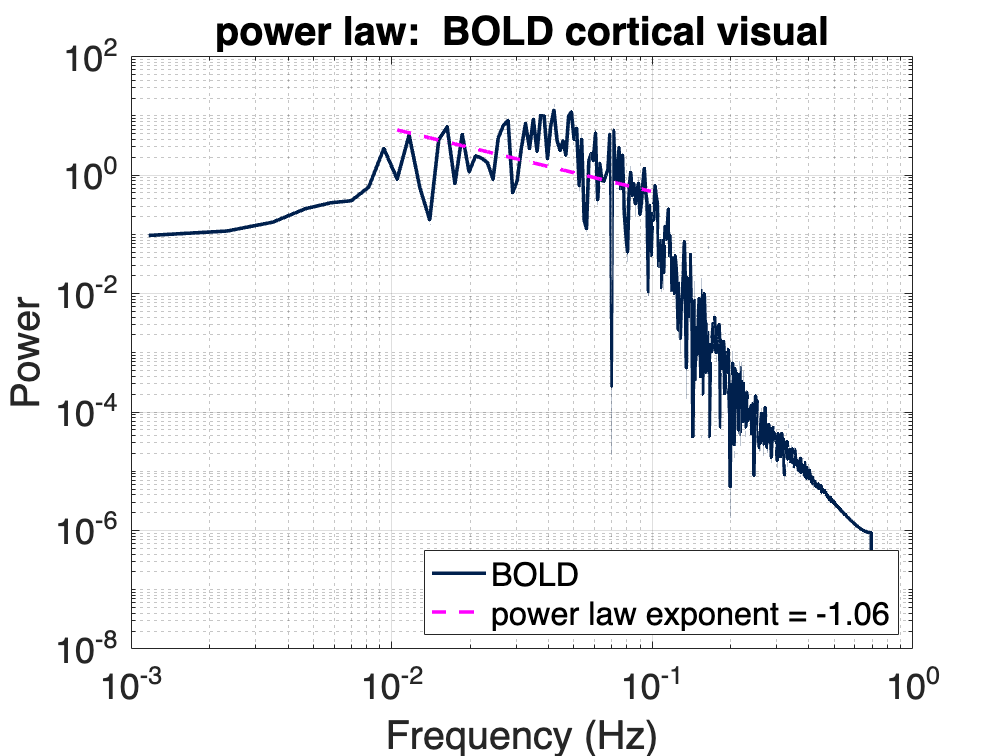

Power law exponent: -1.06


as.fit_power_law(t=t, x=bold_signal_, title="power law:  BOLD " + select_network_type + " " + select_rsn)

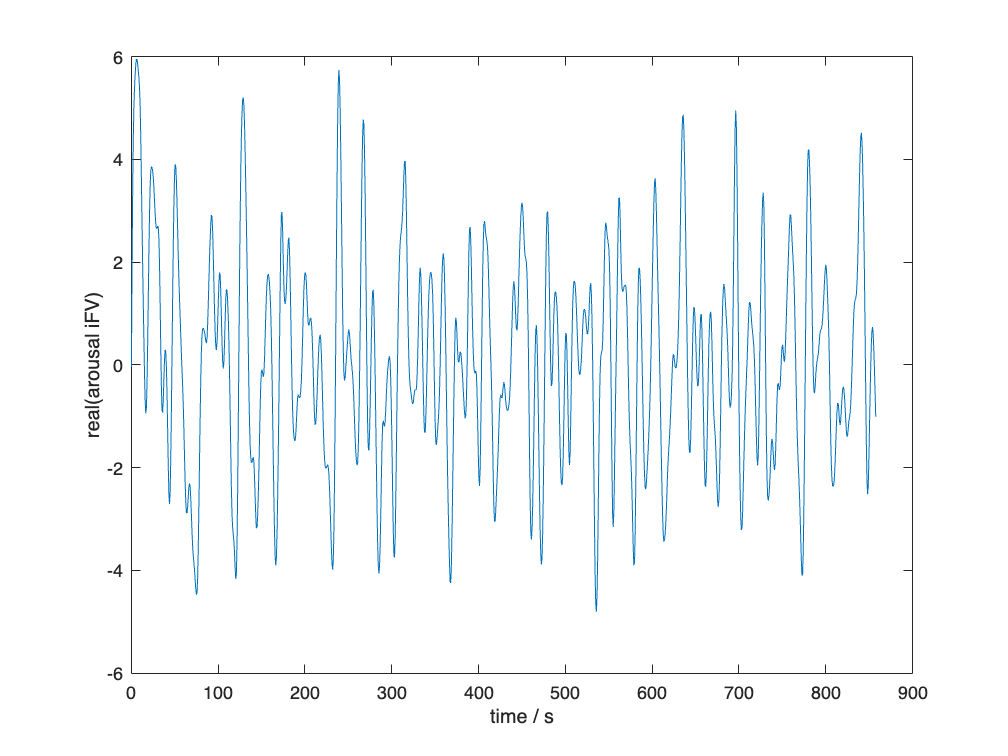

physio_gsr_ = ...
    as.build_global_signal_regressed(as.task_physio(reference=bold_gsr_), is_physio=true);
physio_ = ...
    as.build_band_passed( ...
    as.build_centered_and_rescaled(physio_gsr_, reference=bold_gsr_));

figure; plot(t, physio_(1:num_frames))
ylabel("real(arousal " + as.source_physio + ")")
xlabel("time / s")

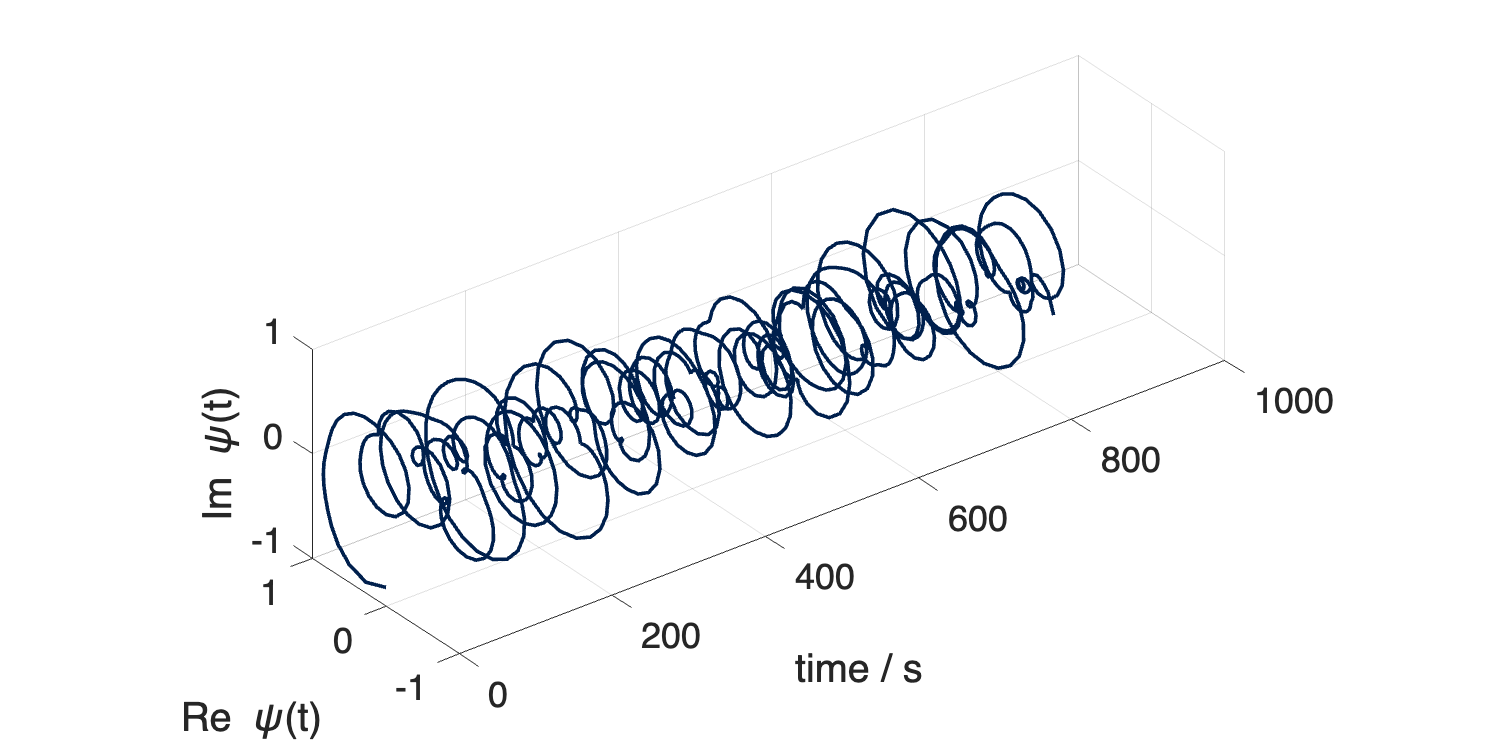

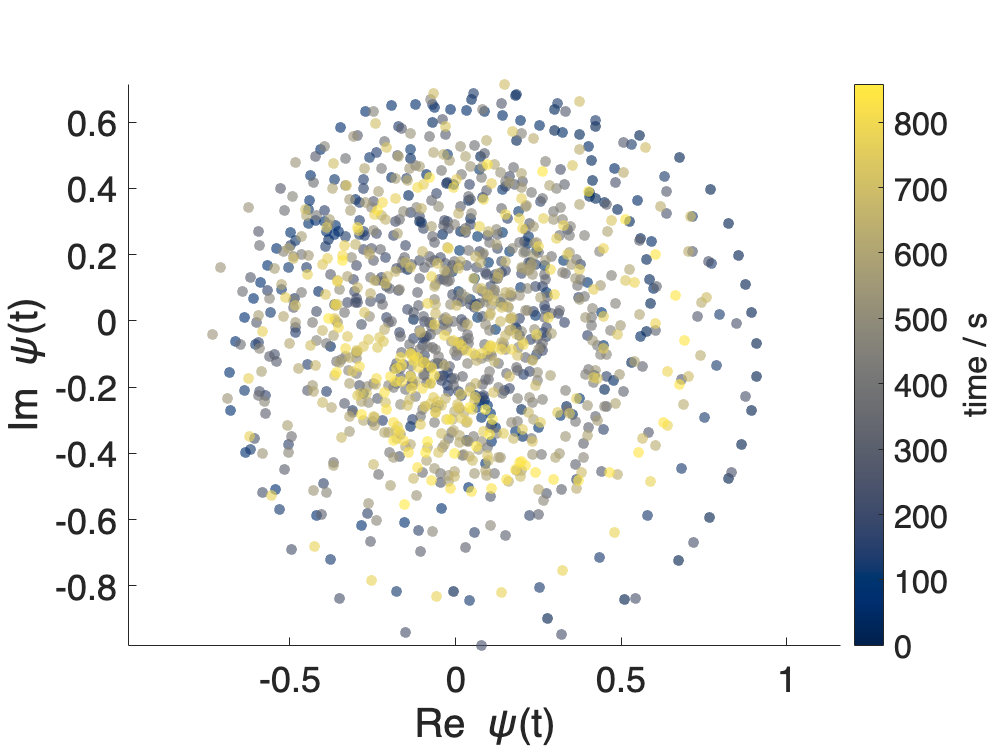


physio_signal_ = ...
    as.build_final_normalization( ...
    hilbert(physio_(1:num_frames, :)));

as.plot3(num_frames=num_frames, t=t, z=physio_signal_, title="")

r = abs(physio_signal_);
theta = angle(physio_signal_);
fprintf("mean(physio(t)) -> %g exp(%gi)\n", mean(r, "all"), mean(theta, "all"))

mean(physio(t)) -> 0.396803 exp(-0.0355618i)


fprintf("median(physio(t)) -> %g exp(%gi)\n", median(r, "all"), median(theta, "all"))

median(physio(t)) -> 0.381116 exp(0.00599536i)


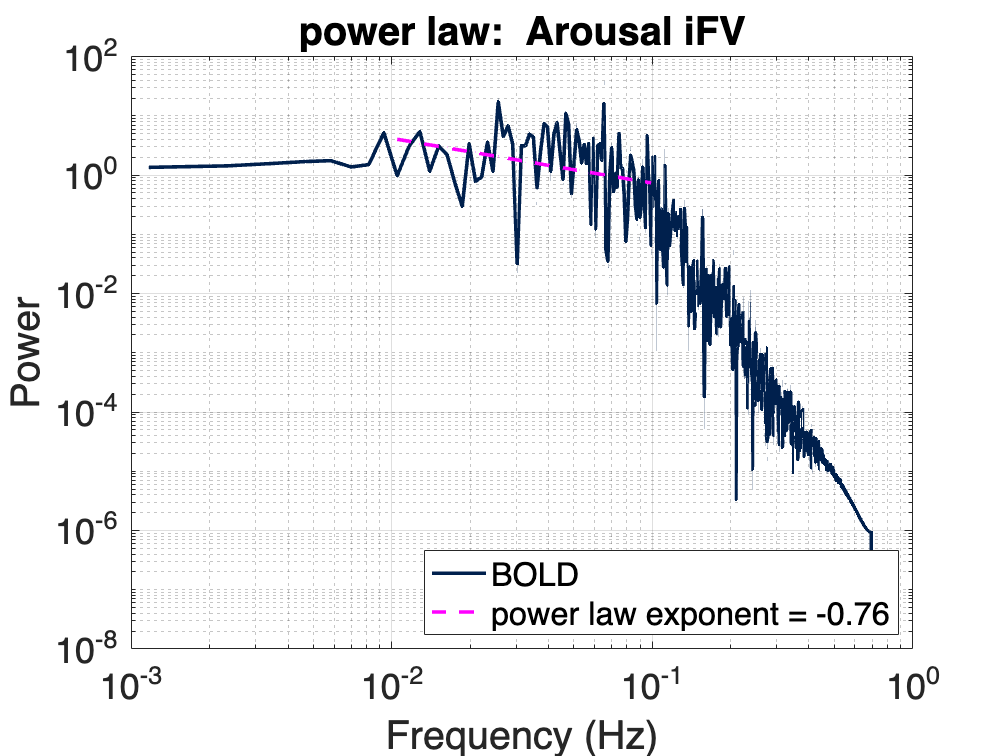

Power law exponent: -0.76


as.fit_power_law(t=t, x=physio_signal_, title="power law:  Arousal " + as.source_physio)

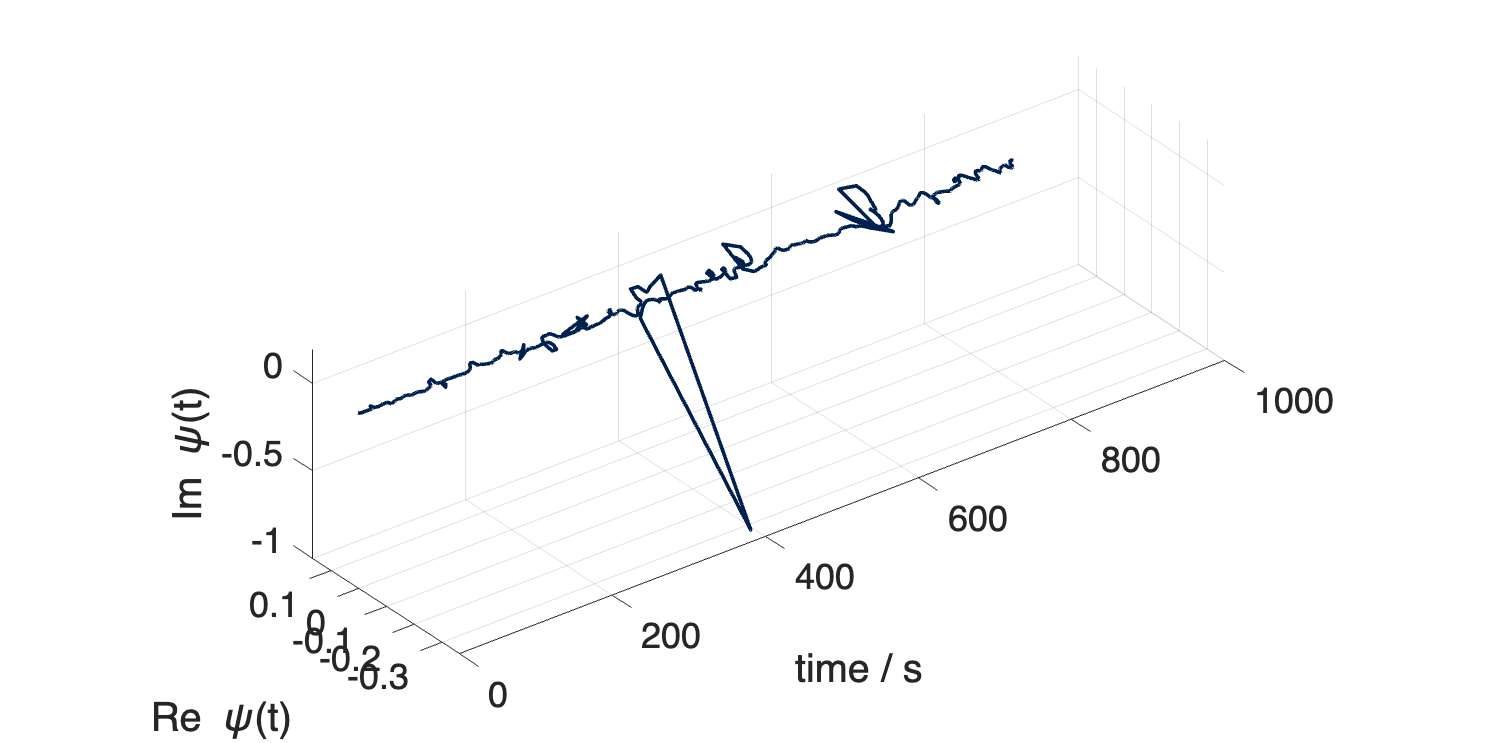

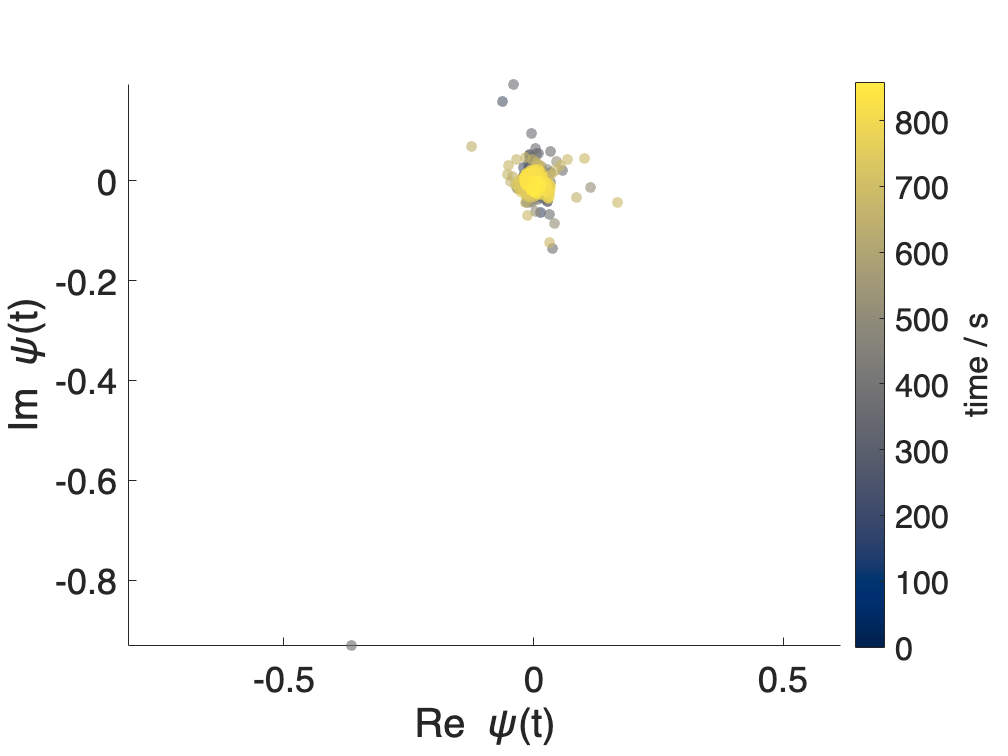

analytic_signal_ = bold_signal_./physio_signal_;
analytic_signal_ = ...
    as.build_final_normalization( ...
    analytic_signal_(1:num_frames, :));

as.plot3(num_frames=num_frames, t=t, z=analytic_signal_, title="")

r = abs(analytic_signal_);
theta = angle(analytic_signal_);
fprintf("mean(analytic(x,t)) -> %g exp(%gi)\n", mean(r, "all"), mean(theta, "all"))

mean(analytic(x,t)) -> 0.0139685 exp(0.0577451i)


fprintf("median(analytic(x,t)) -> %g exp(%gi)\n", median(r, "all"), median(theta, "all"))

median(analytic(x,t)) -> 0.00811165 exp(0.047981i)


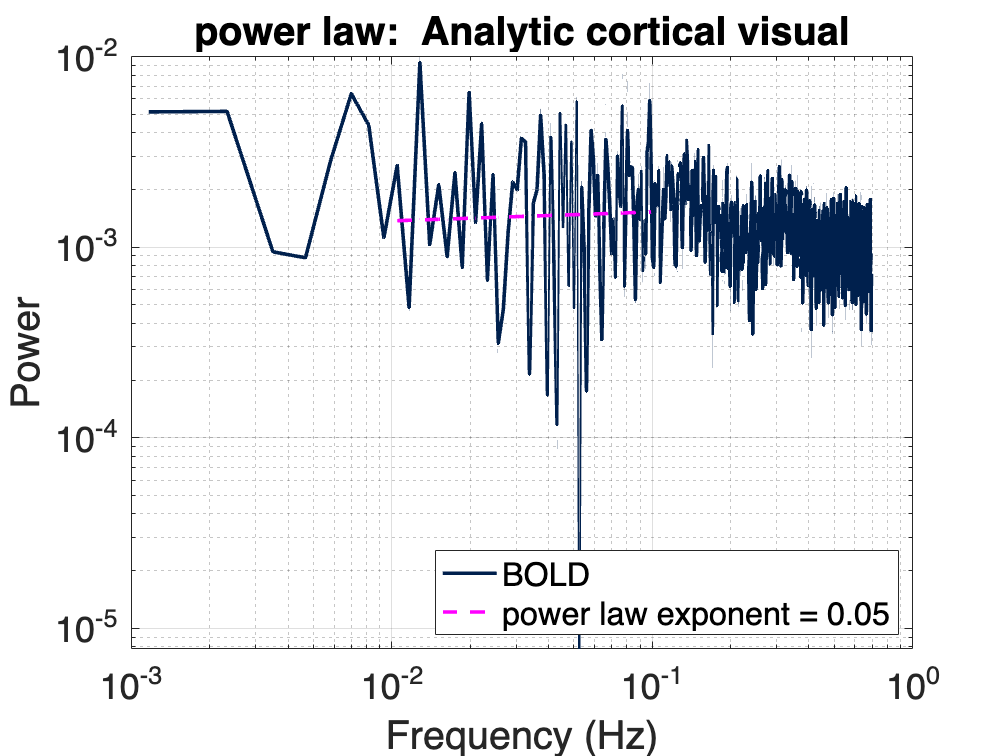

Power law exponent: 0.05


as.fit_power_law(t=t, x=analytic_signal_, title="power law:  Analytic " + select_network_type + " " + select_rsn)